x = 0:0.01:2;
y = 0.5 + x + randn(1, length(x));
data = [x', y'];
dist = pdist2(data, data, "euclidean");

[~,pca_score,~,~,pca_explained,~] = pca(data);
[mds_score, mds_eigenvalue] = cmdscale(dist);

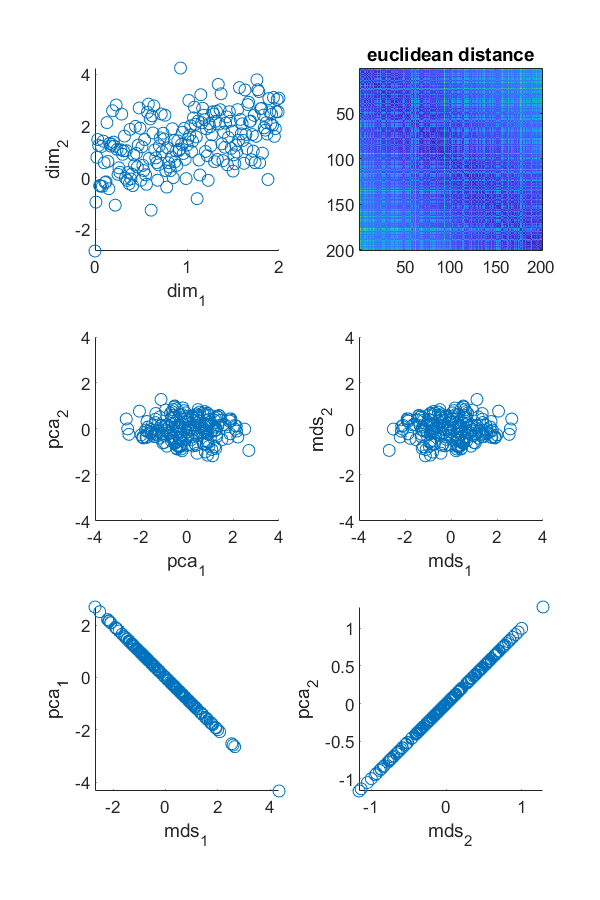

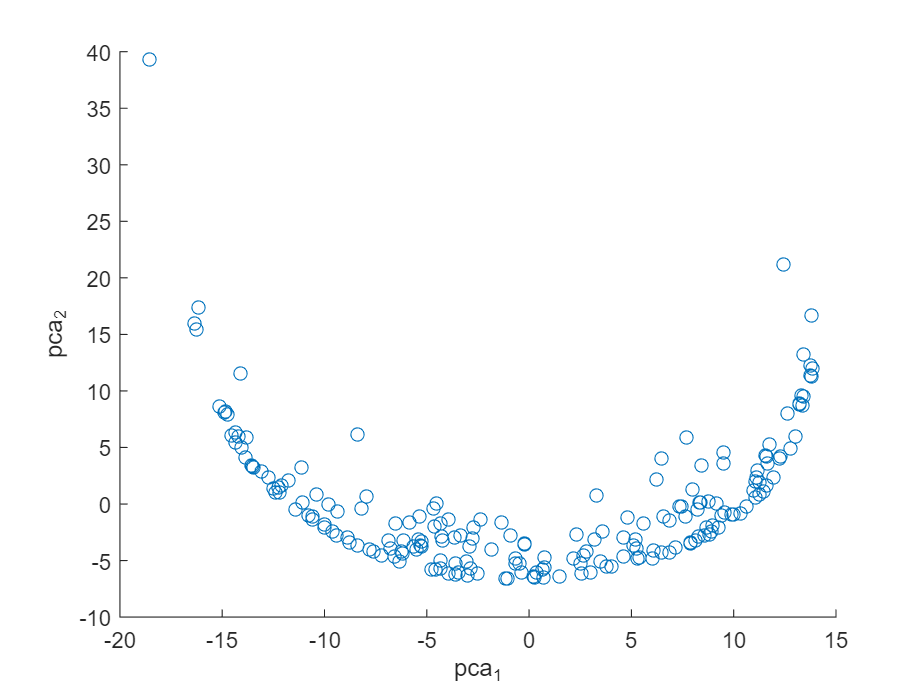

fig = figure('Position', [200 200 400 600]);
subplot(3,2,1)
scatter(x,y);
xlabel('dim_1');
ylabel('dim_2');

subplot(3,2,2);
imagesc(dist);
title('euclidean distance')
axis square;

subplot(3,2,3);
scatter(pca_score(:,1), pca_score(:,2));
xlabel('pca_1'); ylabel('pca_2');
xlim([-4 4]); ylim([-4 4])

subplot(3,2,4);
scatter(mds_score(:,1), mds_score(:,2));
xlabel('mds_1'); ylabel('mds_2');
xlim([-4 4]); ylim([-4 4])

subplot(3,2,5);
scatter(mds_score(:,1), pca_score(:,1));
xlabel('mds_1'); ylabel("pca_1");

subplot(3,2,6);
scatter(mds_score(:,2), pca_score(:,2));
xlabel('mds_2'); ylabel("pca_2");

saveas(gca, 'test_pca_mds.jpg');